% =========================================================================
%  NUMERICAL ANALYSIS OF COOLING EFFICIENCY AND CREEP IN REGENERATIVE
%  SCRAMJET COOLING DUCTS
%
%  Author      : Georgios Miltsios
%  Supervisor  : Professor Christ Lorenz
%  Institution : King's College London, Department of Engineering
%  Date        : April 2026
%
% =========================================================================
%
%  PROJECT OVERVIEW
%  -----------------------------------------------------------------------
%  This script performs a full numerical investigation of a regeneratively
%  cooled scramjet duct operating at Mach 7 heat flux conditions. The
%  analysis spans steady-state and transient thermal regimes, parametric
%  design sweeps, and structural life assessment via Norton-Bailey creep
%  theory. Results are exported in Abaqus-compatible CSV format for
%  subsequent FEA verification.
%
%  OBJECTIVES ADDRESSED
%  -----------------------------------------------------------------------
%  OBJ 1  | Steady-state conduction-convection solver                
%  OBJ 2  | Temperature-dependent wall and coolant properties        
%  OBJ 3  | Parametric study (mdot, t_wall, T_in vs T_max)          
%  OBJ 4  | Transient implicit (backward-Euler) solver            
%  OBJ 5  | Norton-Bailey creep strain and life estimation       
%
%  PHYSICAL MODEL
%  -----------------------------------------------------------------------
%  The duct wall is modelled as a two-layer composite (CuCr1Zr alloy):
%    - Outer layer (hot-gas side): exposed to prescribed heat flux q_flux
%    - Inner layer (coolant side): convectively cooled by hydrogen or RP-1
%
%  The energy equation is solved in two coupled directions:
%    - Thickness direction (x): 1-D Fourier conduction with Neumann BC
%      at the hot face and a convective Robin BC at the coolant face
%    - Axial direction (z): 1-D coolant bulk temperature rise via
%      the steady-flow energy equation / upwind Euler transient update
%
%  Temperature-dependent material and fluid properties (Obj 2) are
%  supplied as anonymous functions and evaluated pointwise at each node,
%  ensuring physically consistent simulation of property variation along
%  and through the duct wall.
%
%  NUMERICAL APPROACH
%  -----------------------------------------------------------------------
%  Steady-state:
%    - Node-by-node iterative two-resistance model (10 iterations max)
%    - Validated against closed-form constant-property reference solution
%    - Mesh independence verified across three grid refinements
%
%  Transient (backward-Euler implicit):
%    - Unconditionally stable for any time-step size (dt = 0.05 s)
%    - Thomas algorithm (tridiagonal solve) per axial station per step
%    - Coupled coolant axial energy updated via upwind Euler
%    - Energy balance error monitored as a validation metric
%
%  RUNTIME OPTIMISATIONS (for tractable laptop execution)
%  -----------------------------------------------------------------------
%  - Coarse grids: Nz = 60 axial nodes, Nx = 20 thickness nodes
%  - Vectorised property evaluations; no inner per-node for-loops where
%    possible
%  - Implicit transient scheme: dt = 0.05 s (vs ~1e-4 s explicit limit)
%  - Parametric sweep: 8 x 7 = 56 solver calls
%  - Snapshot storage: 60 frames total across simulation
%  - Estimated wall-clock time: < 2 minutes on a modern laptop
%
%  OUTPUTS
%  -----------------------------------------------------------------------
%  Figures 1–22 covering: coolant temperature rise; wall temperatures;
%  convection coefficients; through-thickness profiles; parametric heat
%  maps; transient space-time contours; energy balance; mesh independence;
%  validation bar chart; creep accumulation and life.
%
%  ASSUMPTIONS AND LIMITATIONS
%  -----------------------------------------------------------------------
%  - Uniform channel geometry along duct length (no tapering)
%  - Single cooling channel; heat flux applied to one face (W_ch)
%  - Dittus-Boelter Nusselt correlation valid for Re > 10 000, Pr ~ 0.7–160
%  - Norton-Bailey creep constants from open literature for CuCr1Zr alloy
%  - Coarse grids used for runtime; see mesh independence study (Sec. 4)
%  - No radiation heat transfer included
%  - Pressure drop estimated with bulk mean velocity; incompressible

clear; clc; close all;
tic;

fprintf('=================================================================\n');

fprintf('  Regenerative Scramjet Cooling Duct – Optimised MATLAB Analysis\n');

  Regenerative Scramjet Cooling Duct – Optimised MATLAB Analysis


fprintf('=================================================================\n\n');


%% =========================================================================
%  SECTION 0 – GEOMETRY AND BASELINE CONDITIONS
% =========================================================================

% Duct geometry
L_duct = 0.40;          % [m]   axial length
t_wall = 1.0e-3;        % [m]   total wall thickness (baseline)
t1     = 0.50e-3;       % [m]   outer (hot-side) layer thickness
t2     = 0.50e-3;       % [m]   inner (coolant-side) layer thickness

% Hot-gas boundary condition
q_flux = 1.3e6;         % [W/m²]  Mach 7 representative heat flux

% Baseline coolant (hydrogen)
T_cin  = 280;           % [K]   inlet temperature
mdot   = 0.0093;        % [kg/s] mass flow rate

% Channel cross-section
W_ch = 2.0e-3;          % [m]
H_ch = 1.0e-3;          % [m]
A_ch = W_ch * H_ch;     % [m²]
P_ch = 2*(W_ch + H_ch); % [m]  wetted perimeter
D_h  = 4*A_ch / P_ch;   % [m]  hydraulic diameter

% ---- COARSE GRIDS (key optimisation) ----
Nz = 60;                % axial nodes   
Nx = 20;                % thickness nodes 
z  = linspace(0, L_duct, Nz);
x  = linspace(0, t_wall, Nx);
dz = z(2) - z(1);
dx = x(2) - x(1);

% Transient settings – implicit scheme removes stability constraint on dt
t_end   = 3.0;          % [s]
dt      = 0.05;         % [s]  large dt allowed by implicit scheme
t_vec   = 0:dt:t_end;
Nt      = length(t_vec);
N_snap  = 60;           % total snapshots to save
snap_every = max(1, floor(Nt/N_snap));

fprintf('Grid: Nz=%d, Nx=%d | dt=%.3f s | Nt=%d steps\n\n', Nz, Nx, dt, Nt);

Grid: Nz=60, Nx=20 | dt=0.050 s | Nt=61 steps




%% =========================================================================
%  SECTION 1 – MATERIAL AND FLUID PROPERTY FUNCTIONS  (Objective 2)
%  Temperature-dependent properties – CuCr1Zr wall, hydrogen coolant
% =========================================================================

% Wall: Copper-Chromium alloy CuCr1Zr (NASA/ASM handbook data, 250-900 K)
k_w   = @(T) max(10,   330  - 0.10*(T - 300));   % [W/(m·K)]
rho_w = @(T) max(7000, 8900 - 0.20*(T - 300));   % [kg/m³]
cp_w  = @(T) min(500,  385  + 0.05*(T - 300));   % [J/(kg·K)]

% Thermal / mechanical constants for stress and creep
alpha_th = 17e-6;       % [1/K]   CTE
E_mod    = 120e9;       % [Pa]    Young's modulus
nu       = 0.34;        % [-]     Poisson's ratio

% Hydrogen coolant (~280-350 K, supercritical, 10 MPa)
cp_H2 = @(T) 14300 + 0.5*(T - 280);
mu_H2 = @(T) max(5e-6, 1.2e-5 - 2e-8*(T - 280));
k_H2  = @(T) 0.18  + 3e-4*(T - 280);
Pr_H2 = @(T) cp_H2(T) .* mu_H2(T) ./ k_H2(T);

% RP-1 hydrocarbon coolant (kerosene, ~300-450 K, 5 MPa)
cp_R  = @(T) 2000 + 1.2*(T - 300);
mu_R  = @(T) max(2e-4, 8e-4 - 2e-6*(T - 300));
k_R   = @(T) 0.13  + 1e-4*(T - 300);
Pr_R  = @(T) cp_R(T) .* mu_R(T) ./ k_R(T);

% Dittus-Boelter Nusselt correlation
Nu_DB = @(Re, Pr) 0.023 .* Re.^0.8 .* Pr.^0.4;

% Friction factor (Blasius turbulent / Hagen-Poiseuille laminar)
f_fr  = @(Re) (Re < 2300).*(64./Re) + (Re >= 2300).*(0.316.*Re.^-0.25);

%% =========================================================================
%  SECTION 2 – ANALYTICAL VALIDATION BASELINE  (Validation V1)
%  Closed-form two-resistance model at constant reference properties
% =========================================================================
fprintf('--- V1: Analytical validation ---\n');

--- V1: Analytical validation ---



T_ref  = 330;
Tc_ref = 300;
Re_ref = mdot * D_h / (A_ch * mu_H2(Tc_ref));
Nu_ref = Nu_DB(Re_ref, Pr_H2(Tc_ref));
h_ref  = Nu_ref * k_H2(Tc_ref) / D_h;

T_min_a = T_cin  + q_flux / h_ref;
T_med_a = T_min_a + q_flux * t2 / k_w(T_ref);
T_max_a = T_med_a + q_flux * t1 / k_w(T_ref);

fprintf('  h_ref       = %6.0f  W/(m²·K)\n', h_ref);

  h_ref       = 117188  W/(m²·K)


fprintf('  T_min (anal)= %6.1f  K\n', T_min_a);

  T_min (anal)=  291.1  K


fprintf('  T_med (anal)= %6.1f  K\n', T_med_a);

  T_med (anal)=  293.1  K


fprintf('  T_max (anal)= %6.1f  K\n\n', T_max_a);

  T_max (anal)=  295.1  K




%% =========================================================================
%  SECTION 3 – STEADY-STATE SOLVER  (Objectives 1, 2)
% =========================================================================
fprintf('--- OBJ 1/2: Steady-state solver ---\n');

--- OBJ 1/2: Steady-state solver ---



[Tc_ss, Twi_ss, Two_ss, h_ss, Re_ss] = ss_solver(z, Nz, dz, t1, t2, ...
    q_flux, T_cin, mdot, D_h, A_ch, W_ch, ...
    k_w, cp_H2, mu_H2, k_H2, Pr_H2, Nu_DB);

err_max = abs(Two_ss(1) - T_max_a) / T_max_a * 100;
err_min = abs(Twi_ss(1) - T_min_a) / T_min_a * 100;
fprintf('  T_max numerical = %.1f K  |  analytical = %.1f K  |  err = %.2f%%\n', ...
    Two_ss(1), T_max_a, err_max);

  T_max numerical = 295.4 K  |  analytical = 295.1 K  |  err = 0.11%


fprintf('  T_min numerical = %.1f K  |  analytical = %.1f K  |  err = %.2f%%\n\n', ...
    Twi_ss(1), T_min_a, err_min);

  T_min numerical = 293.4 K  |  analytical = 291.1 K  |  err = 0.80%




[Tc_RP1, Twi_RP1, Two_RP1, h_RP1, Re_RP1] = ss_solver(z, Nz, dz, t1, t2, ...
    q_flux, T_cin, mdot, D_h, A_ch, W_ch, ...
    k_w, cp_R, mu_R, k_R, Pr_R, Nu_DB);
fprintf('  H2  T_max = %.1f K  |  RP-1 T_max = %.1f K  |  advantage = %.1f K\n\n', ...
    max(Two_ss), max(Two_RP1), max(Two_RP1)-max(Two_ss));

  H2  T_max = 303.1 K  |  RP-1 T_max = 494.2 K  |  advantage = 191.2 K




rho_approx = 10;
V_ax       = mdot / (rho_approx * A_ch);
dP_ax      = cumsum(f_fr(Re_ss) .* (dz/D_h) .* 0.5 .* rho_approx .* V_ax^2);

%% =========================================================================
%  SECTION 3b – OBJECTIVE 2 VISUALISATION
%  Temperature-dependent property curves and impact on results
% =========================================================================
fprintf('--- OBJ 2: Temperature-dependent property visualisation ---\n');

--- OBJ 2: Temperature-dependent property visualisation ---


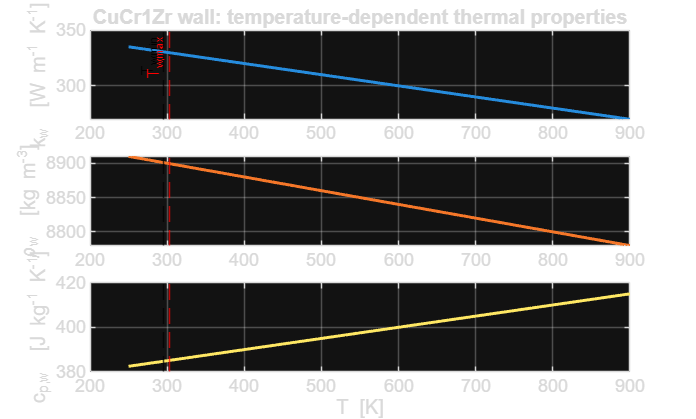


T_range    = linspace(250, 900, 200);
kw_range   = arrayfun(k_w,   T_range);
rhow_range = arrayfun(rho_w, T_range);
cpw_range  = arrayfun(cp_w,  T_range);

figure('Name','FigA1 Wall material properties vs T');
col_prop = lines(3);
subplot(3,1,1);
plot(T_range, kw_range, 'Color', col_prop(1,:), 'LineWidth', 1.5);
ylabel('k_w  [W m^{-1} K^{-1}]');
title('CuCr1Zr wall: temperature-dependent thermal properties');
grid on; box on;
xline(min(Two_ss), '--k', 'T_{w,min}', 'LabelHorizontalAlignment', 'left', 'FontSize', 8);
xline(max(Two_ss), '--r', 'T_{w,max}', 'LabelHorizontalAlignment', 'left', 'FontSize', 8);
subplot(3,1,2);
plot(T_range, rhow_range, 'Color', col_prop(2,:), 'LineWidth', 1.5);
ylabel('\rho_w  [kg m^{-3}]');
grid on; box on;
xline(min(Two_ss), '--k', 'FontSize', 8);
xline(max(Two_ss), '--r', 'FontSize', 8);
subplot(3,1,3);
plot(T_range, cpw_range, 'Color', col_prop(3,:), 'LineWidth', 1.5);
xlabel('T  [K]');  ylabel('c_{p,w}  [J kg^{-1} K^{-1}]');
grid on; box on;
xline(min(Two_ss), '--k', 'FontSize', 8);
xline(max(Two_ss), '--r', 'FontSize', 8);


fprintf('  Property range across duct:\n');

  Property range across duct:


fprintf('    k_w  :  %.1f → %.1f  W/(m·K)\n',  k_w(min(Two_ss)),  k_w(max(Two_ss)));

    k_w  :  330.5 → 329.7  W/(m·K)


fprintf('    rho_w:  %.0f → %.0f  kg/m³\n',    rho_w(min(Two_ss)), rho_w(max(Two_ss)));

    rho_w:  8901 → 8899  kg/m³


fprintf('    cp_w :  %.1f → %.1f  J/(kg·K)\n', cp_w(min(Two_ss)),  cp_w(max(Two_ss)));

    cp_w :  384.8 → 385.2  J/(kg·K)


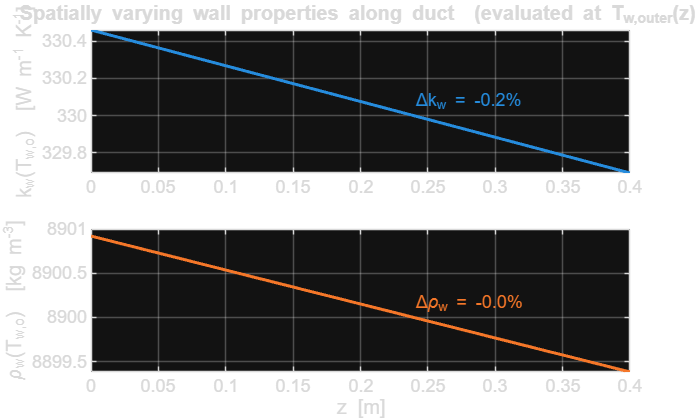


kw_axial   = arrayfun(k_w,   Two_ss);
rhow_axial = arrayfun(rho_w, Two_ss);

figure('Name','FigA2 Spatially varying wall properties along duct');
subplot(2,1,1);
plot(z, kw_axial, 'Color', col_prop(1,:), 'LineWidth', 1.5);
ylabel('k_w(T_{w,o})  [W m^{-1} K^{-1}]');
title('Spatially varying wall properties along duct  (evaluated at T_{w,outer}(z))');
grid on; box on;
dk = (kw_axial(end) - kw_axial(1)) / kw_axial(1) * 100;
text(z(end)*0.6, mean(kw_axial), sprintf('\\Deltak_w = %.1f%%', dk), ...
    'FontSize', 9, 'Color', col_prop(1,:));
subplot(2,1,2);
plot(z, rhow_axial, 'Color', col_prop(2,:), 'LineWidth', 1.5);
xlabel('z  [m]');  ylabel('\rho_w(T_{w,o})  [kg m^{-3}]');
grid on; box on;
drho = (rhow_axial(end) - rhow_axial(1)) / rhow_axial(1) * 100;
text(z(end)*0.6, mean(rhow_axial), sprintf('\\Delta\\rho_w = %.1f%%', drho), ...
    'FontSize', 9, 'Color', col_prop(2,:));


k_w_const   = @(T) k_w(T_cin)   * ones(size(T));
rho_w_const = @(T) rho_w(T_cin) * ones(size(T));
cp_w_const  = @(T) cp_w(T_cin)  * ones(size(T));

[Tc_const, Twi_const, Two_const, ~, ~] = ss_solver(z, Nz, dz, t1, t2, ...
    q_flux, T_cin, mdot, D_h, A_ch, W_ch, ...
    k_w_const, cp_H2, mu_H2, k_H2, Pr_H2, Nu_DB);

fprintf('  T_max (variable k):  %.2f K\n', max(Two_ss));

  T_max (variable k):  303.08 K


fprintf('  T_max (constant k):  %.2f K\n', max(Two_const));

  T_max (constant k):  303.06 K


fprintf('  Difference:          %.2f K  (%.2f%%)\n', ...
    max(Two_const) - max(Two_ss), ...
    (max(Two_const) - max(Two_ss)) / max(Two_ss) * 100);

  Difference:          -0.02 K  (-0.01%)


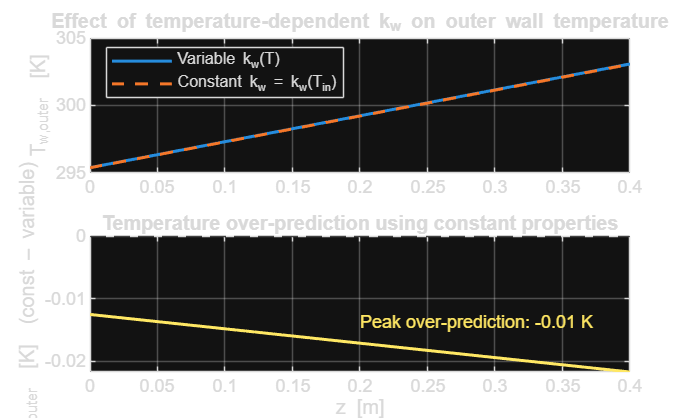


figure('Name','FigA3 Variable vs constant property comparison');
subplot(2,1,1);
plot(z, Two_ss,    'Color', col_prop(1,:), 'LineWidth', 1.5, ...
    'DisplayName', 'Variable k_w(T)');
hold on;
plot(z, Two_const, 'Color', col_prop(2,:), 'LineWidth', 1.5, 'LineStyle', '--', ...
    'DisplayName', 'Constant k_w = k_w(T_{in})');
ylabel('T_{w,outer}  [K]');
title('Effect of temperature-dependent k_w on outer wall temperature');
legend('Location', 'northwest');
grid on; box on;
subplot(2,1,2);
plot(z, Two_const - Two_ss, 'Color', col_prop(3,:), 'LineWidth', 1.5);
xlabel('z  [m]');
ylabel('\DeltaT_{outer}  [K]  (const – variable)');
title('Temperature over-prediction using constant properties');
yline(0, 'k--');
grid on; box on;
text(z(end)*0.5, mean(Two_const - Two_ss) * 0.8, ...
    sprintf('Peak over-prediction: %.2f K', max(Two_const - Two_ss)), ...
    'FontSize', 9, 'Color', col_prop(3,:));


fprintf('  Figures A1–A3 generated for Objective 2.\n\n');

  Figures A1–A3 generated for Objective 2.




%% =========================================================================
%  SECTION 4 – MESH INDEPENDENCE  (Validation V2)
% =========================================================================
fprintf('--- V2: Mesh independence ---\n');

--- V2: Mesh independence ---



Nz_test   = [30, 60, 120];
Tmax_mesh = zeros(1,3);
for ii = 1:3
    Nz_i = Nz_test(ii);
    z_i  = linspace(0, L_duct, Nz_i);
    dz_i = z_i(2)-z_i(1);
    [~,~,Two_i,~,~] = ss_solver(z_i, Nz_i, dz_i, t1, t2, q_flux, T_cin, ...
        mdot, D_h, A_ch, W_ch, k_w, cp_H2, mu_H2, k_H2, Pr_H2, Nu_DB);
    Tmax_mesh(ii) = max(Two_i);
    fprintf('  Nz = %3d  →  T_max = %.3f K\n', Nz_i, Tmax_mesh(ii));
end

  Nz =  30  →  T_max = 303.078 K
  Nz =  60  →  T_max = 303.078 K
  Nz = 120  →  T_max = 303.078 K


merr = abs(diff(Tmax_mesh))./Tmax_mesh(2:end)*100;
fprintf('  Convergence: %.3f%% (30→60)  |  %.3f%% (60→120)\n', merr(1), merr(2));

  Convergence: 0.000% (30→60)  |  0.000% (60→120)


if all(merr < 2)
    fprintf('  ✓  Mesh independence confirmed  (<2%% criterion)\n\n');
else
    fprintf('  ⚠  Consider further refinement\n\n');
end

  ✓  Mesh independence confirmed  (<2% criterion)




%% =========================================================================
%  SECTION 5 – PARAMETRIC STUDY  (Objective 3)
% =========================================================================
fprintf('--- OBJ 3: Parametric study ---\n');

--- OBJ 3: Parametric study ---



mdot_vec  = linspace(0.004, 0.020, 8);
twall_vec = linspace(0.6e-3, 1.6e-3, 7);
Tin_vec   = [250, 280, 310];

Tmax_map = zeros(length(twall_vec), length(mdot_vec));
sig_map  = zeros(length(twall_vec), length(mdot_vec));
dP_map   = zeros(length(twall_vec), length(mdot_vec));

for ii = 1:length(twall_vec)
    tw = twall_vec(ii);
    for jj = 1:length(mdot_vec)
        md = mdot_vec(jj);
        [~, Twi_p, Two_p, h_p, Re_p] = ss_solver(z, Nz, dz, tw/2, tw/2, ...
            q_flux, T_cin, md, D_h, A_ch, W_ch, ...
            k_w, cp_H2, mu_H2, k_H2, Pr_H2, Nu_DB);
        Tmax_map(ii,jj) = max(Two_p);

        dT = max(Two_p) - min(Twi_p);
        sig_map(ii,jj) = E_mod * alpha_th * dT / (1 - nu) / 1e6;

        Re_m = mean(Re_p);
        fm   = f_fr(Re_m);
        dP_map(ii,jj) = fm * (L_duct/D_h) * 0.5 * rho_approx * V_ax^2;
    end
end

mid_tw  = round(length(twall_vec)/2);
mid_md  = round(length(mdot_vec)/2);
Tmax_vs_mdot  = Tmax_map(mid_tw, :);
Tmax_vs_twall = Tmax_map(:, mid_md)';

Tmax_vs_Tin = zeros(1, length(Tin_vec));
for ii = 1:length(Tin_vec)
    [~,~,Two_t,~,~] = ss_solver(z, Nz, dz, t1, t2, q_flux, Tin_vec(ii), ...
        mdot, D_h, A_ch, W_ch, k_w, cp_H2, mu_H2, k_H2, Pr_H2, Nu_DB);
    Tmax_vs_Tin(ii) = max(Two_t);
end

fprintf('  T_max range (mdot sweep):  %.1f – %.1f K\n', ...
    min(Tmax_vs_mdot), max(Tmax_vs_mdot));

  T_max range (mdot sweep):  294.1 – 324.4 K


fprintf('  T_max range (twall sweep): %.1f – %.1f K\n', ...
    min(Tmax_vs_twall), max(Tmax_vs_twall));

  T_max range (twall sweep): 299.1 – 303.0 K


fprintf('  Parametric study complete.\n\n');

  Parametric study complete.




%% =========================================================================
%  SECTION 6 – TRANSIENT SOLVER  (Stretch Objective 5)
%  Backward-Euler implicit through-thickness scheme
% =========================================================================
fprintf('--- STRETCH 5: Transient implicit solver ---\n');

--- STRETCH 5: Transient implicit solver ---



T_ref_w = 400;
k_ref   = k_w(T_ref_w);
rho_ref = rho_w(T_ref_w);
cp_ref  = cp_w(T_ref_w);
alpha_d = k_ref / (rho_ref * cp_ref);
r       = alpha_d * dt / dx^2;

fprintf('  alpha = %.3e m²/s | r = %.2f (backward-Euler: unconditionally stable)\n', ...
    alpha_d, r);

  alpha = 9.240e-05 m²/s | r = 1667.82 (backward-Euler: unconditionally stable)



a_diag = 1 + 2*r;
b_off  = -r;
d_rhs  = zeros(Nx,1);

T_wall = T_cin * ones(Nx, Nz);
Tc_now = T_cin * ones(1,  Nz);

h_now = zeros(1, Nz);
for j = 1:Nz
    mu_j     = mu_H2(Tc_now(j));
    Re_j     = mdot * D_h / (A_ch * mu_j);
    h_now(j) = Nu_DB(Re_j, Pr_H2(Tc_now(j))) * k_H2(Tc_now(j)) / D_h;
end

T_snap     = zeros(Nx, N_snap);
Tc_snap    = zeros(Nz, N_snap);
Two_snap   = zeros(Nz, N_snap);
t_snap     = zeros(1,  N_snap);
Q_in_snap  = zeros(1,  N_snap);
Q_out_snap = zeros(1,  N_snap);
i_snap     = 0;
Q_in_cum   = 0;
Q_out_cum  = 0;

for n = 1:Nt

    T_new  = T_wall;
    Tc_new = Tc_now;

    % ---- 1. Backward-Euler through-thickness solve at each axial station --
    for j = 1:Nz
        Tc_j  = Tc_now(j);
        h_j   = h_now(j);
        T_col = T_wall(:, j);

        d_rhs(2:Nx-1) = T_col(2:Nx-1);

        k1        = k_w(T_col(1));
        a_hot     = 1 + 2*r;
        b_hot     = -2*r;
        d_rhs(1)  = T_col(1) + 2*r*dx*q_flux/k1;

        k_end     = k_w(T_col(Nx));
        Bi        = h_j * dx / k_end;
        a_cold    = 1 + 2*r + 2*r*Bi;
        b_cold    = -2*r;
        d_rhs(Nx) = T_col(Nx) + 2*r*Bi*Tc_j;

        c_fwd    = zeros(Nx-1, 1);
        d_fwd    = zeros(Nx,   1);

        c_fwd(1) = b_hot / a_hot;
        d_fwd(1) = d_rhs(1) / a_hot;

        for i = 2:Nx-1
            denom    = a_diag - b_off * c_fwd(i-1);
            c_fwd(i) = b_off  / denom;
            d_fwd(i) = (d_rhs(i) - b_off * d_fwd(i-1)) / denom;
        end

        denom_end  = a_cold - b_cold * c_fwd(Nx-1);
        d_fwd(Nx)  = (d_rhs(Nx) - b_cold * d_fwd(Nx-1)) / denom_end;

        T_col_new        = zeros(Nx, 1);
        T_col_new(Nx)    = d_fwd(Nx);
        for i = Nx-1:-1:1
            T_col_new(i) = d_fwd(i) - c_fwd(i) * T_col_new(i+1);
        end
        T_new(:, j) = T_col_new;
    end

    % ---- 2. Coolant axial energy equation (upwind Euler) -----------------
    %        Uses W_ch (one heated face) for physical consistency
    Tc_new(1) = T_cin;
    for j = 2:Nz
        cp_j      = cp_H2(Tc_now(j-1));
        q_conv_j  = h_now(j) * W_ch * dz * (T_new(Nx,j) - Tc_now(j-1));
        Tc_new(j) = Tc_now(j-1) + q_conv_j / (mdot * cp_j);
        Tc_new(j) = max(Tc_new(j), T_cin);
    end

    % ---- 3. Update convection coefficients --------------------------------
    for j = 1:Nz
        mu_j     = mu_H2(Tc_new(j));
        Re_j     = mdot * D_h / (A_ch * mu_j);
        h_now(j) = Nu_DB(Re_j, Pr_H2(Tc_new(j))) * k_H2(Tc_new(j)) / D_h;
    end

    T_wall = T_new;
    Tc_now = Tc_new;

    % ---- 4. Energy balance (instantaneous, single heated face) -----------
    cp_mean    = cp_H2(mean(Tc_now));
    Q_in_inst  = q_flux * L_duct * W_ch;
    Q_out_inst = mdot * cp_mean * max(0, Tc_now(end) - T_cin);
    Q_in_cum   = Q_in_cum  + Q_in_inst  * dt;
    Q_out_cum  = Q_out_cum + Q_out_inst * dt;

    % ---- 5. Snapshots -----------------------------------------------------
    if mod(n, snap_every) == 0 && i_snap < N_snap
        i_snap = i_snap + 1;
        mid_z  = round(Nz/2);
        T_snap(:, i_snap)   = T_wall(:, mid_z);
        Tc_snap(:, i_snap)  = Tc_now';
        Two_snap(:, i_snap) = T_wall(1, :)';
        t_snap(i_snap)      = n * dt;
        Q_in_snap(i_snap)   = Q_in_cum;
        Q_out_snap(i_snap)  = Q_out_cum;
    end
end

% Trim snapshots
ns        = i_snap;
t_snap    = t_snap(1:ns);
T_snap    = T_snap(:,1:ns);
Tc_snap   = Tc_snap(:,1:ns);
Two_snap  = Two_snap(:,1:ns);
Q_in_snap = Q_in_snap(1:ns);
Q_out_snap= Q_out_snap(1:ns);

% ---- Instantaneous energy balance at end of simulation (steady-state) ---
cp_final    = cp_H2(mean(Tc_now));
Q_in_final  = q_flux * L_duct * W_ch;
Q_out_final = mdot * cp_final * (Tc_now(end) - T_cin);
EB_err      = (Q_in_final - Q_out_final) / Q_in_final * 100;

fprintf('  Transient complete.  Energy balance error = %.2f%%\n', EB_err);

  Transient complete.  Energy balance error = -0.16%


if abs(EB_err) < 2
    fprintf('  ✓  Within 2%% target\n\n');
else
    fprintf('  ⚠  Exceeds 2%% – consider reducing dt\n\n');
end

  ✓  Within 2% target




Thot_mid  = T_snap(1,  :);
Tcold_mid = T_snap(end,:);
Tc_z0     = Tc_snap(1,   :);
Tc_zL2    = Tc_snap(round(Nz/2), :);
Tc_zL     = Tc_snap(end, :);
Two_z0    = Two_snap(1,   :);
Two_zL2   = Two_snap(round(Nz/2),:);
Two_zL    = Two_snap(end, :);

%% =========================================================================
%  SECTION 7 – NORTON-BAILEY CREEP ESTIMATION  (Stretch Objective 7)
% =========================================================================
fprintf('--- STRETCH 7: Norton-Bailey creep ---\n');

--- STRETCH 7: Norton-Bailey creep ---



A_NB = 1.8e-15;
n_NB = 4.5;
Q_NB = 1.5e5;
R_g  = 8.314;

t_flight = 300;
N_cyc    = 10;

dT_duct  = Two_ss - Twi_ss;
sig_duct = E_mod * alpha_th .* dT_duct ./ (1 - nu) ./ 1e6;

eps_dot   = A_NB .* sig_duct.^n_NB .* exp(-Q_NB ./ (R_g .* Two_ss));
eps_total = eps_dot * t_flight * N_cyc;
eps_limit = 0.01;
N_life    = eps_limit ./ (eps_dot * t_flight);
N_life(eps_dot == 0) = Inf;

fprintf('  Max thermal stress  = %.1f MPa\n', max(sig_duct));

  Max thermal stress  = 6.1 MPa


fprintf('  Max creep strain rate = %.3e s⁻¹\n', max(eps_dot));

  Max creep strain rate = 8.584e-38 s⁻¹


fprintf('  Accumulated creep (%d cycles) = %.5f%%\n', N_cyc, max(eps_total)*100);

  Accumulated creep (10 cycles) = 0.00000%


fprintf('  Estimated creep life = %.0f cycles\n\n', min(N_life(isfinite(N_life))));

  Estimated creep life = 388305129959086948575143683686400 cycles




%% =========================================================================
%  SECTION 8 – ABAQUS EXPORT  (Objective 4)
% =========================================================================
fprintf('--- OBJ 4: Abaqus export ---\n');

--- OBJ 4: Abaqus export ---



x_mm = x * 1e3;

fid = fopen('Abaqus_SS_Tfield.csv','w');
fprintf(fid,'x_mm,z_m,T_K\n');
for jj = 1:Nz
    T_col_j = linspace(Two_ss(jj), Twi_ss(jj), Nx);
    for ii = 1:Nx
        fprintf(fid,'%.5f,%.5f,%.4f\n', x_mm(ii), z(jj), T_col_j(ii));
    end
end
fclose(fid);

fid2 = fopen('Abaqus_Trans_Tfield_tend.csv','w');
fprintf(fid2,'x_mm,z_m,T_K\n');
for jj = 1:Nz
    T_col_j = linspace(T_wall(1,jj), T_wall(Nx,jj), Nx);
    for ii = 1:Nx
        fprintf(fid2,'%.5f,%.5f,%.4f\n', x_mm(ii), z(jj), T_col_j(ii));
    end
end
fclose(fid2);

fid3 = fopen('Abaqus_NortonBailey.csv','w');
fprintf(fid3,'T_K,sigma_MPa,eps_dot_per_s\n');
for Ti = 300:100:900
    for si = [100 300 500 700 900]
        er = A_NB * si^n_NB * exp(-Q_NB/(R_g*Ti));
        fprintf(fid3,'%.0f,%.0f,%.6e\n', Ti, si, er);
    end
end
fclose(fid3);

fprintf('  Abaqus_SS_Tfield.csv\n');

  Abaqus_SS_Tfield.csv


fprintf('  Abaqus_Trans_Tfield_tend.csv\n');

  Abaqus_Trans_Tfield_tend.csv


fprintf('  Abaqus_NortonBailey.csv\n\n');

  Abaqus_NortonBailey.csv




%% =========================================================================
%  SECTION 9 – FIGURES
% =========================================================================
fprintf('--- Generating figures ---\n');

--- Generating figures ---


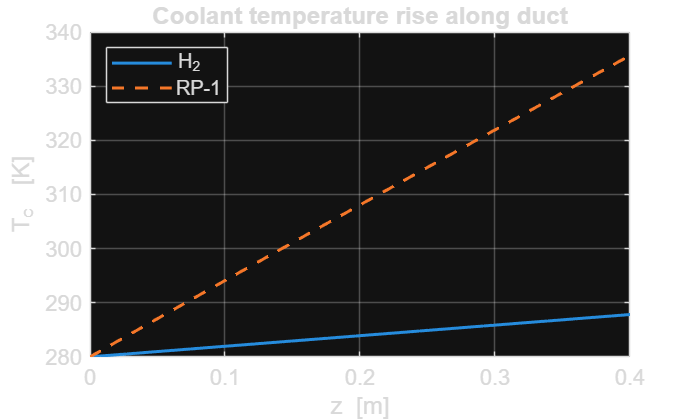


set(0,'DefaultAxesFontSize',11,'DefaultLineLineWidth',1.5,'DefaultFigureColor','w');
col = lines(6);

figure('Name','Fig1 Coolant T rise');
plot(z, Tc_ss,  'Color',col(1,:), 'DisplayName','H_2');
hold on;
plot(z, Tc_RP1, 'Color',col(2,:), 'LineStyle','--', 'DisplayName','RP-1');
xlabel('z  [m]');  ylabel('T_c  [K]');
title('Coolant temperature rise along duct');
legend('Location','northwest');  grid on;  box on;

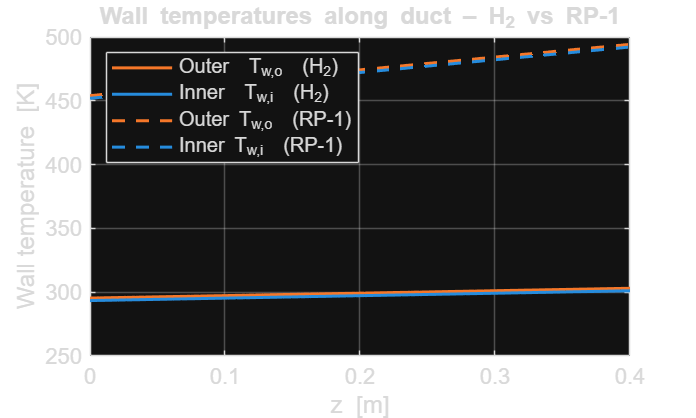


figure('Name','Fig2 Wall T along duct');
plot(z, Two_ss,  'Color',col(2,:), 'DisplayName','Outer  T_{w,o}  (H_2)');
hold on;
plot(z, Twi_ss,  'Color',col(1,:), 'DisplayName','Inner  T_{w,i}  (H_2)');
plot(z, Two_RP1, 'Color',col(2,:), 'LineStyle','--', 'DisplayName','Outer T_{w,o}  (RP-1)');
plot(z, Twi_RP1, 'Color',col(1,:), 'LineStyle','--', 'DisplayName','Inner T_{w,i}  (RP-1)');
xlabel('z  [m]');  ylabel('Wall temperature  [K]');
title('Wall temperatures along duct – H_2 vs RP-1');
legend('Location','northwest');  grid on;  box on;

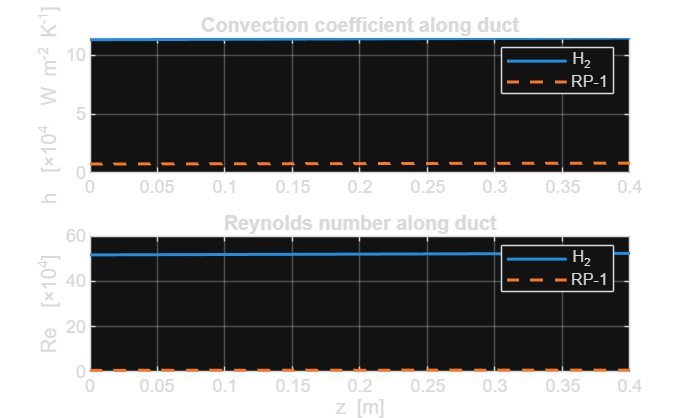


figure('Name','Fig3 h and Re');
subplot(2,1,1);
plot(z, h_ss/1e4,  'Color',col(1,:), 'DisplayName','H_2');
hold on;
plot(z, h_RP1/1e4, 'Color',col(2,:), 'LineStyle','--', 'DisplayName','RP-1');
ylabel('h  [×10^4  W m^{-2} K^{-1}]');
title('Convection coefficient along duct');
legend;  grid on;
subplot(2,1,2);
plot(z, Re_ss/1e4,  'Color',col(1,:), 'DisplayName','H_2');
hold on;
plot(z, Re_RP1/1e4, 'Color',col(2,:), 'LineStyle','--', 'DisplayName','RP-1');
xlabel('z  [m]');  ylabel('Re  [×10^4]');
title('Reynolds number along duct');
legend;  grid on;

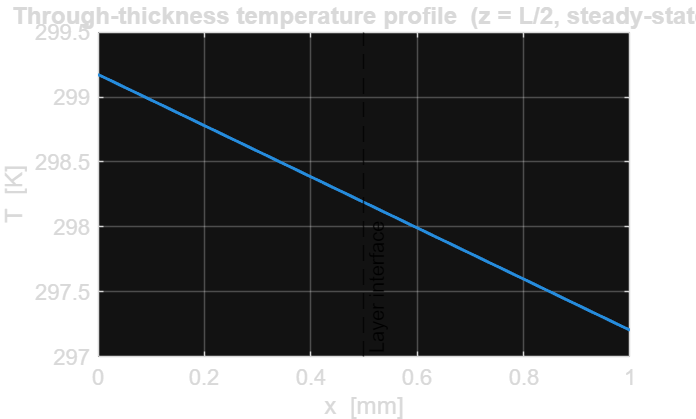


T_thk_ss = linspace(Two_ss(round(Nz/2)), Twi_ss(round(Nz/2)), Nx);
figure('Name','Fig4 Through-thickness profile');
plot(x_mm, T_thk_ss, 'Color',col(1,:));
xline(t1*1e3, 'k--', 'Layer interface', 'LabelVerticalAlignment','bottom');
xlabel('x  [mm]');  ylabel('T  [K]');
title('Through-thickness temperature profile  (z = L/2, steady-state)');
grid on;  box on;
text(0.05, T_thk_ss(1)-8,   sprintf('T_{max}=%.0f K', T_thk_ss(1)),  'FontSize',9);
text(t_wall*1e3-0.08, T_thk_ss(end)+4, sprintf('T_{min}=%.0f K', T_thk_ss(end)), ...
    'FontSize',9, 'HorizontalAlignment','right');

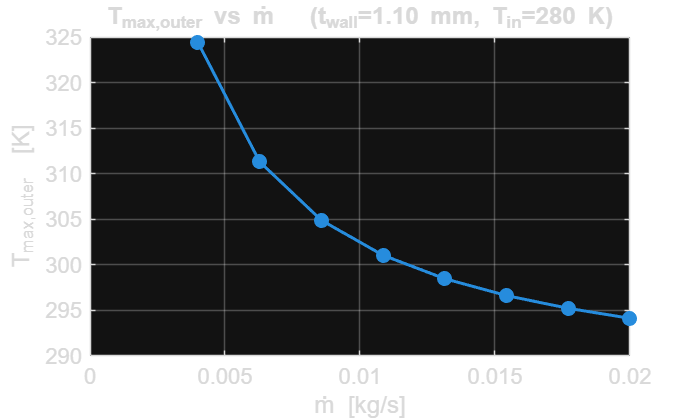


figure('Name','Fig5 Tmax vs mdot');
plot(mdot_vec, Tmax_vs_mdot, 'o-', 'Color',col(1,:), 'MarkerSize',6, ...
    'MarkerFaceColor',col(1,:));
xlabel('ṁ  [kg/s]');  ylabel('T_{max,outer}  [K]');
title(sprintf('T_{max,outer} vs ṁ   (t_{wall}=%.2f mm, T_{in}=%.0f K)', ...
    twall_vec(mid_tw)*1e3, T_cin));
grid on;  box on;

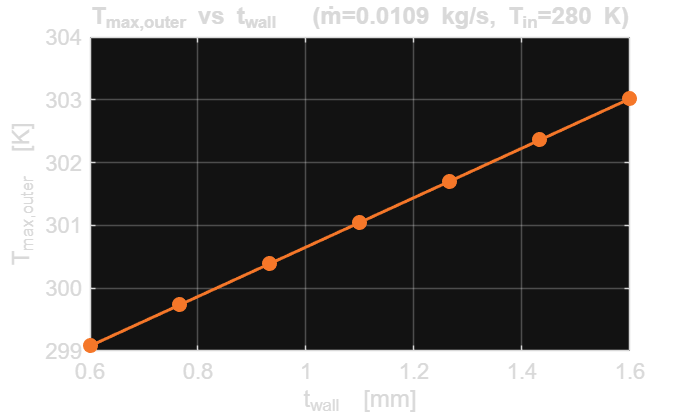


figure('Name','Fig6 Tmax vs twall');
plot(twall_vec*1e3, Tmax_vs_twall, 'o-', 'Color',col(2,:), 'MarkerSize',6, ...
    'MarkerFaceColor',col(2,:));
xlabel('t_{wall}  [mm]');  ylabel('T_{max,outer}  [K]');
title(sprintf('T_{max,outer} vs t_{wall}   (ṁ=%.4f kg/s, T_{in}=%.0f K)', ...
    mdot_vec(mid_md), T_cin));
grid on;  box on;

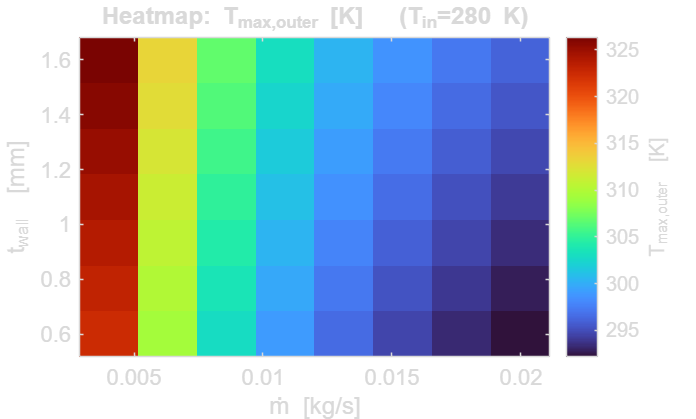


figure('Name','Fig7 Heatmap Tmax');
imagesc(mdot_vec, twall_vec*1e3, Tmax_map);
set(gca,'YDir','normal');
colormap(turbo);
cb = colorbar;  cb.Label.String = 'T_{max,outer}  [K]';
xlabel('ṁ  [kg/s]');  ylabel('t_{wall}  [mm]');
title(sprintf('Heatmap: T_{max,outer} [K]   (T_{in}=%.0f K)', T_cin));
box on;

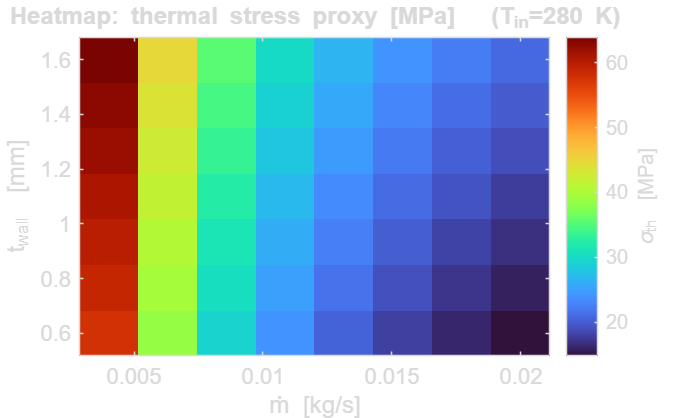


figure('Name','Fig8 Heatmap Stress');
imagesc(mdot_vec, twall_vec*1e3, sig_map);
set(gca,'YDir','normal');
colormap(turbo);
cb = colorbar;  cb.Label.String = '\sigma_{th}  [MPa]';
xlabel('ṁ  [kg/s]');  ylabel('t_{wall}  [mm]');
title(sprintf('Heatmap: thermal stress proxy [MPa]   (T_{in}=%.0f K)', T_cin));
box on;

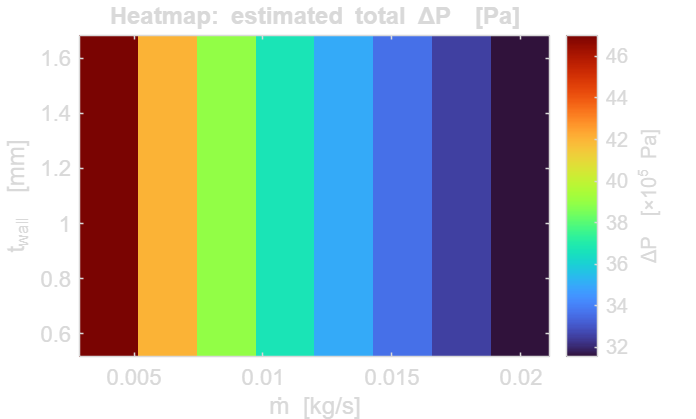


figure('Name','Fig9 Heatmap dP');
imagesc(mdot_vec, twall_vec*1e3, dP_map/1e5);
set(gca,'YDir','normal');
colormap(turbo);
cb = colorbar;  cb.Label.String = '\DeltaP  [×10^5 Pa]';
xlabel('ṁ  [kg/s]');  ylabel('t_{wall}  [mm]');
title('Heatmap: estimated total \DeltaP  [Pa]');
box on;

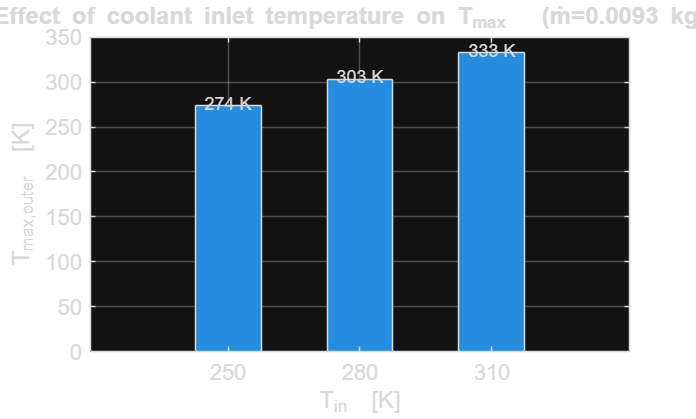


figure('Name','Fig10 Tmax vs Tin');
bar(Tin_vec, Tmax_vs_Tin, 0.5, 'FaceColor',col(1,:));
xlabel('T_{in}  [K]');  ylabel('T_{max,outer}  [K]');
title(sprintf('Effect of coolant inlet temperature on T_{max}   (ṁ=%.4f kg/s)', mdot));
grid on;  box on;
for ii = 1:length(Tin_vec)
    text(Tin_vec(ii), Tmax_vs_Tin(ii)+2, sprintf('%.0f K', Tmax_vs_Tin(ii)), ...
        'HorizontalAlignment','center','FontSize',9);
end

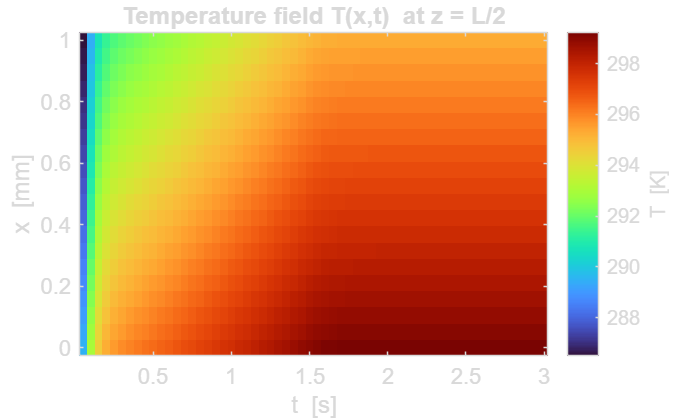


figure('Name','Fig11 Transient Txt heatmap');
imagesc(t_snap, x_mm, T_snap);
set(gca,'YDir','normal');
colormap(turbo);
cb = colorbar;  cb.Label.String = 'T  [K]';
xlabel('t  [s]');  ylabel('x  [mm]');
title('Temperature field T(x,t)  at z = L/2');
box on;

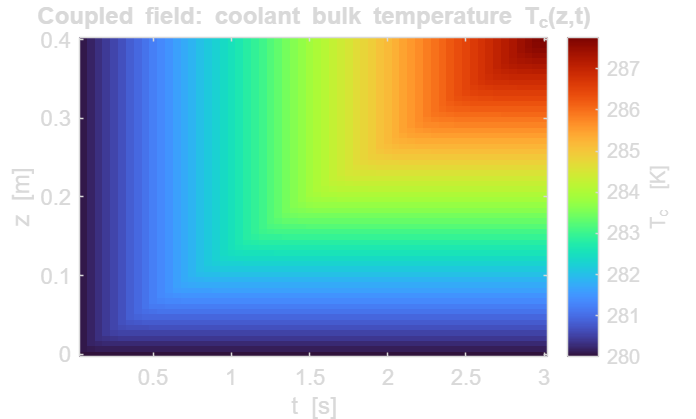


figure('Name','Fig12 Tc zt heatmap');
imagesc(t_snap, z, Tc_snap);
set(gca,'YDir','normal');
colormap(turbo);
cb = colorbar;  cb.Label.String = 'T_c  [K]';
xlabel('t  [s]');  ylabel('z  [m]');
title('Coupled field: coolant bulk temperature T_c(z,t)');
box on;

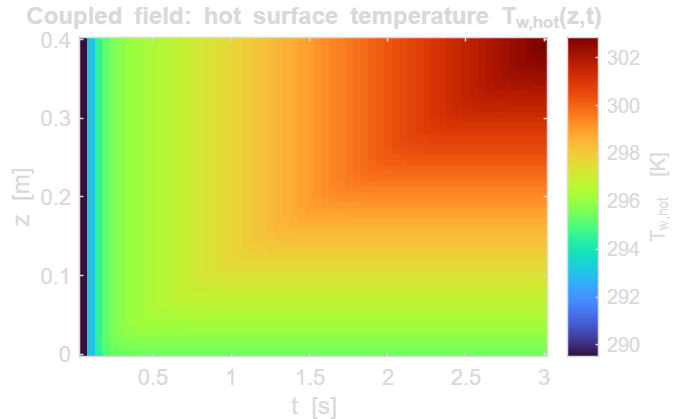


figure('Name','Fig13 Twot heatmap');
imagesc(t_snap, z, Two_snap);
set(gca,'YDir','normal');
colormap(turbo);
cb = colorbar;  cb.Label.String = 'T_{w,hot}  [K]';
xlabel('t  [s]');  ylabel('z  [m]');
title('Coupled field: hot surface temperature T_{w,hot}(z,t)');
box on;

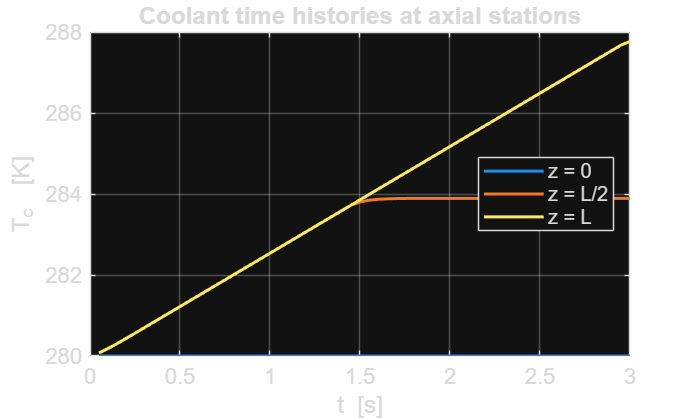


figure('Name','Fig14 Tc time histories');
plot(t_snap, Tc_z0,  'Color',col(1,:), 'DisplayName','z = 0');
hold on;
plot(t_snap, Tc_zL2, 'Color',col(2,:), 'DisplayName','z = L/2');
plot(t_snap, Tc_zL,  'Color',col(3,:), 'DisplayName','z = L');
xlabel('t  [s]');  ylabel('T_c  [K]');
title('Coolant time histories at axial stations');
legend('Location','east');  grid on;  box on;

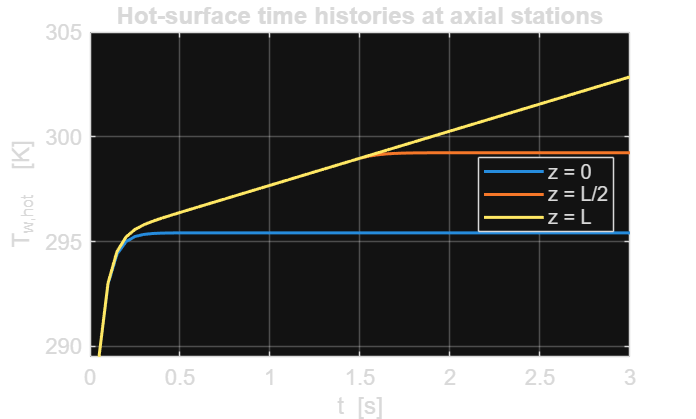


figure('Name','Fig15 Thot time histories');
plot(t_snap, Two_z0,  'Color',col(1,:), 'DisplayName','z = 0');
hold on;
plot(t_snap, Two_zL2, 'Color',col(2,:), 'DisplayName','z = L/2');
plot(t_snap, Two_zL,  'Color',col(3,:), 'DisplayName','z = L');
xlabel('t  [s]');  ylabel('T_{w,hot}  [K]');
title('Hot-surface time histories at axial stations');
legend('Location','east');  grid on;  box on;

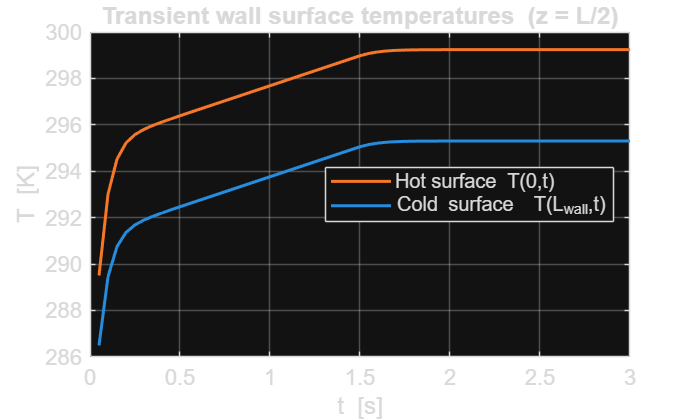


figure('Name','Fig16 Transient surface T');
plot(t_snap, Thot_mid,  'Color',col(2,:), 'DisplayName','Hot surface  T(0,t)');
hold on;
plot(t_snap, Tcold_mid, 'Color',col(1,:), 'DisplayName','Cold surface  T(L_{wall},t)');
xlabel('t  [s]');  ylabel('T  [K]');
title('Transient wall surface temperatures  (z = L/2)');
legend('Location','east');  grid on;  box on;

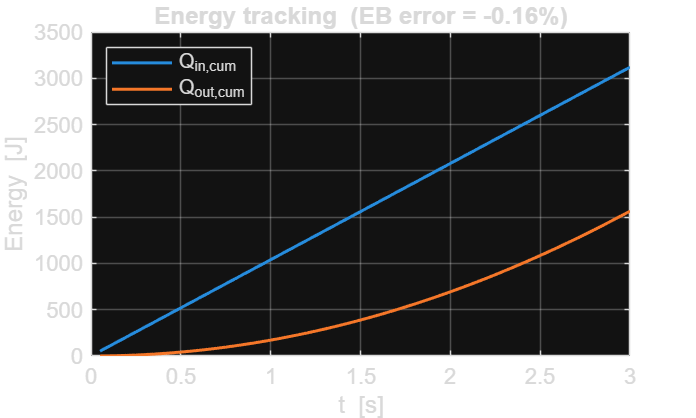


figure('Name','Fig17 Energy balance');
plot(t_snap, Q_in_snap,  'Color',col(1,:), 'DisplayName','Q_{in,cum}');
hold on;
plot(t_snap, Q_out_snap, 'Color',col(2,:), 'DisplayName','Q_{out,cum}');
xlabel('t  [s]');  ylabel('Energy  [J]');
title(sprintf('Energy tracking  (EB error = %.2f%%)', EB_err));
legend('Location','northwest');  grid on;  box on;

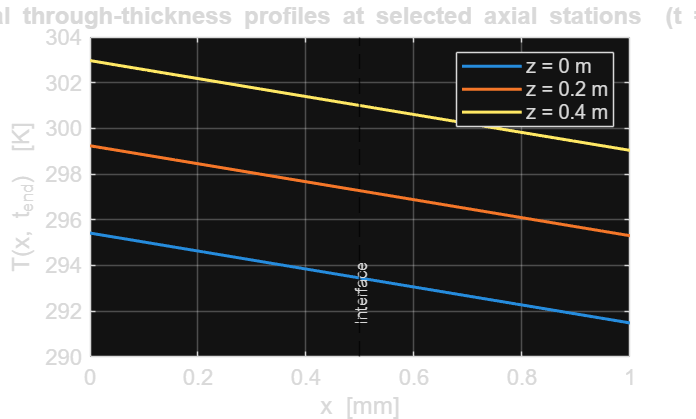


T_fin_z0  = T_wall(:, 1);
T_fin_zL2 = T_wall(:, round(Nz/2));
T_fin_zL  = T_wall(:, Nz);
figure('Name','Fig18 Final through-thickness profiles');
plot(x_mm, T_fin_z0,  'Color',col(1,:), 'DisplayName','z = 0 m');
hold on;
plot(x_mm, T_fin_zL2, 'Color',col(2,:), 'DisplayName','z = 0.2 m');
plot(x_mm, T_fin_zL,  'Color',col(3,:), 'DisplayName','z = 0.4 m');
xline(t1*1e3, 'k--', 'HandleVisibility','off');
text(t1*1e3+0.02, min(T_fin_z0)*0.9999, 'Interface', ...
    'FontSize',8,'Rotation',90,'VerticalAlignment','bottom');
xlabel('x  [mm]');  ylabel('T(x, t_{end})  [K]');
title('Final through-thickness profiles at selected axial stations  (t = t_{end})');
legend('Location','northeast');  grid on;  box on;

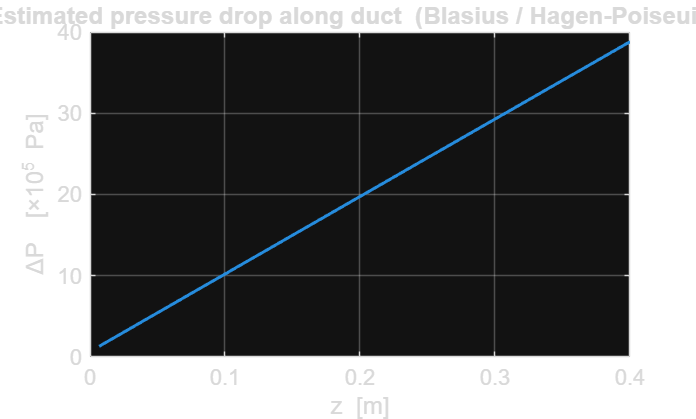


figure('Name','Fig19 Pressure drop');
plot(z(2:end), dP_ax(2:end)/1e5, 'Color',col(1,:));
xlabel('z  [m]');  ylabel('\DeltaP  [×10^5 Pa]');
title('Estimated pressure drop along duct  (Blasius / Hagen-Poiseuille)');
grid on;  box on;

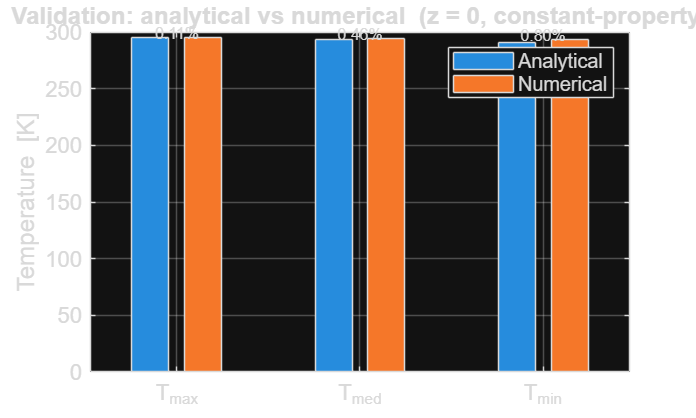


figure('Name','Fig20 Validation');
lbl = {'T_{max}','T_{med}','T_{min}'};
T_num  = [Two_ss(1), (Two_ss(1)+Twi_ss(1))/2, Twi_ss(1)];
T_anal = [T_max_a,   T_med_a,                  T_min_a];
b = bar([T_anal; T_num]', 0.7);
b(1).FaceColor = col(1,:);  b(2).FaceColor = col(2,:);
set(gca,'XTickLabel', lbl);
ylabel('Temperature  [K]');
title('Validation: analytical vs numerical  (z = 0, constant-property)');
legend({'Analytical','Numerical'}, 'Location','northeast');
grid on;  box on;
for ii = 1:3
    err_i = abs(T_num(ii)-T_anal(ii))/T_anal(ii)*100;
    text(ii, max(T_anal(ii),T_num(ii))+3, sprintf('%.2f%%',err_i), ...
        'HorizontalAlignment','center','FontSize',8);
end

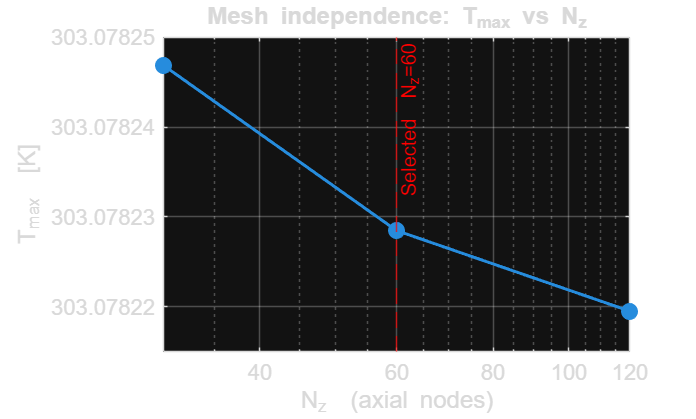


figure('Name','Fig21 Mesh independence');
semilogx(Nz_test, Tmax_mesh, 'o-', 'Color',col(1,:), ...
    'MarkerSize',7, 'MarkerFaceColor',col(1,:));
xline(Nz, 'r--', sprintf('Selected  N_z=%d', Nz));
xlabel('N_z  (axial nodes)');  ylabel('T_{max}  [K]');
title('Mesh independence: T_{max} vs N_z');
grid on;  box on;

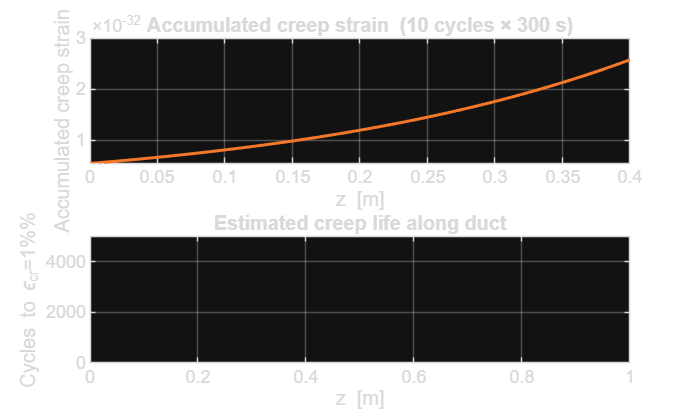


figure('Name','Fig22 Creep');
subplot(2,1,1);
plot(z, eps_total*100, 'Color',col(2,:));
xlabel('z  [m]');  ylabel('Accumulated creep strain  [%]');
title(sprintf('Accumulated creep strain  (%d cycles × %.0f s)', N_cyc, t_flight));
grid on;  box on;
subplot(2,1,2);
plot(z, N_life, 'Color',col(1,:));
xlabel('z  [m]');  ylabel('Cycles to \epsilon_{cr}=1%%');
title('Estimated creep life along duct');
ylim([0, min(5000, 1.2*max(N_life(isfinite(N_life))))]);
grid on;  box on;


fprintf('  22 figures generated.\n\n');

  22 figures generated.




%% =========================================================================
%  SECTION 10 – SUMMARY
% =========================================================================
elapsed = toc;
fprintf('=================================================================\n');

fprintf('  RESULTS SUMMARY\n');

  RESULTS SUMMARY


fprintf('=================================================================\n');

fprintf('  STEADY-STATE  (H2, baseline)\n');

  STEADY-STATE  (H2, baseline)


fprintf('    T_max hot wall        = %.1f K  (%.1f °C)\n', max(Two_ss), max(Two_ss)-273.15);

    T_max hot wall        = 303.1 K  (29.9 °C)


fprintf('    T_min coolant wall    = %.1f K  (%.1f °C)\n', min(Twi_ss), min(Twi_ss)-273.15);

    T_min coolant wall    = 293.4 K  (20.3 °C)


fprintf('    Coolant exit temp     = %.1f K\n', Tc_ss(end));

    Coolant exit temp     = 287.8 K


fprintf('    Max Re                = %.0f  (turbulent)\n', max(Re_ss));

    Max Re                = 523489  (turbulent)


fprintf('  COOLANT COMPARISON\n');

  COOLANT COMPARISON


fprintf('    H2  T_max             = %.1f K\n', max(Two_ss));

    H2  T_max             = 303.1 K


fprintf('    RP-1 T_max            = %.1f K\n', max(Two_RP1));

    RP-1 T_max            = 494.2 K


fprintf('    H2 cooling advantage  = %.1f K\n', max(Two_RP1)-max(Two_ss));

    H2 cooling advantage  = 191.2 K


fprintf('  PARAMETRIC STUDY\n');

  PARAMETRIC STUDY


fprintf('    Min T_max achievable  = %.1f K\n', min(Tmax_map(:)));

    Min T_max achievable  = 292.2 K


fprintf('    Max T_max (worst)     = %.1f K\n', max(Tmax_map(:)));

    Max T_max (worst)     = 326.4 K


fprintf('  TRANSIENT  (backward-Euler implicit, dt=%.3f s)\n', dt);

  TRANSIENT  (backward-Euler implicit, dt=0.050 s)


fprintf('    Energy balance error  = %.2f%%\n', EB_err);

    Energy balance error  = -0.16%


fprintf('  VALIDATION\n');

  VALIDATION


fprintf('    Anal. vs num. T_max   = %.2f%% error\n', err_max);

    Anal. vs num. T_max   = 0.11% error


fprintf('    Mesh conv. (60→120)   = %.3f%%\n', merr(2));

    Mesh conv. (60→120)   = 0.000%


fprintf('  CREEP  (Norton-Bailey)\n');

  CREEP  (Norton-Bailey)


fprintf('    Max thermal stress    = %.1f MPa\n', max(sig_duct));

    Max thermal stress    = 6.1 MPa


fprintf('    Creep life estimate   = %.0f cycles\n', min(N_life(isfinite(N_life))));

    Creep life estimate   = 388305129959086948575143683686400 cycles


fprintf('  Wall-clock runtime      = %.1f s\n', elapsed);

  Wall-clock runtime      = 5.7 s


fprintf('=================================================================\n');

fprintf('  Abaqus CSV files written to working directory.\n');

  Abaqus CSV files written to working directory.


fprintf('=================================================================\n');


%% =========================================================================
%  LOCAL FUNCTION
%  W_ch added as input argument for physical consistency of coolant update
% =========================================================================

function [Tc, Twi, Two, h_ax, Re_ax] = ss_solver( ...
        z, Nz, dz, t1, t2, q_flux, T_cin, mdot, ...
        D_h, A_ch, W_ch, k_wfn, cp_fn, mu_fn, k_cfn, Pr_fn, Nu_fn)

    Tc    = zeros(1, Nz);  Tc(1) = T_cin;
    Twi   = zeros(1, Nz);
    Two   = zeros(1, Nz);
    h_ax  = zeros(1, Nz);
    Re_ax = zeros(1, Nz);

    for j = 1:Nz
        Tcj = Tc(j);

        cp_c = cp_fn(Tcj);
        mu_c = mu_fn(Tcj);
        k_c  = k_cfn(Tcj);
        Pr_c = Pr_fn(Tcj);
        Re   = mdot * D_h / (A_ch * mu_c);
        Nu   = Nu_fn(Re, Pr_c);
        h    = Nu * k_c / D_h;
        Re_ax(j) = Re;
        h_ax(j)  = h;

        Twi_j = Tcj + q_flux / h;
        Two_j = Twi_j + q_flux * (t2/k_wfn(Twi_j) + t1/k_wfn(Twi_j));
        for iter = 1:10
            Twi_new = Tcj  + q_flux * (1/h + t2/k_wfn((Twi_j + Tcj)/2));
            Two_new = Twi_new + q_flux * t1 / k_wfn((Two_j + Twi_new)/2);
            if abs(Twi_new - Twi_j) < 0.05 && abs(Two_new - Two_j) < 0.05
                break
            end
            Twi_j = Twi_new;
            Two_j = Two_new;
        end
        Twi(j) = Twi_new;
        Two(j) = Two_new;

        % Coolant axial energy balance – W_ch (one heated face) for
        % physical consistency with the energy balance check
        if j < Nz
            Tc(j+1) = Tcj + q_flux * W_ch * dz / (mdot * cp_c);
        end
    end
end